# XPlane NN Error Plots

This program aims to provide insight in characterizing the output behahavior of a NN by plotting the output and error in output against state information from randomly generated data. 

clear variables; close all; clc;

## CSV Reader

%Make sure necessary data has been moved over to the MATLAB folder 
csvData1 = readtable('./4-2/4-2/combined_states.csv') %50m, OOD by 0

csvData1 = 74999×8 table
    error_h     error_y       phi        theta        psi         x          y         h   
    _______    _________    ________    ________    _______    _______    _______    ______

     34.222     0.088819     -3.4351     -2.6207      1.398     24.998     12.998    390.24
    -26.055    -0.038139     -4.1568    -0.44122    -1.6325    -3.9993     19.999    415.24
     32.441        1.048      6.0254     -2.6809     3.0883     42.999    -47.002    386.24
     8.4522     -0.11681    -0.73337     0.71421     3.3602         20        -21    377.24
     3.0986      0.10814      1.6568      0.8225    -2.9189     42.999    -50.002    375.24
    -13.949     -0.35816      3.6728     0.61137    0.5002

csvData2 = readtable('./4-2/4-2/generated_states.csv')

csvData2 = 74999×3 table
     y_err     h_err_NN    h_err_true
    _______    ________    __________

     12.909    -11.471       -45.693 
     20.037    -38.746       -12.691 
     -48.05    -6.7686       -39.209 
    -20.883    0.70505       -7.7472 
    -50.111     3.1466      0.047929 
     2.3582    -10.696        3.2534 
    -27.893     -17.78       -11.266 
    -6.0173     12.324       -18.375 
     26.681    -6.0223        11.584 
     38.154    -14.254       -6.2575 
     39.822    -25.865       -14.428 
    -6.1093    -35.748       -26.432 
     46.407     7.7901       -35.952 
     48.742    -39.365        7.1605 
    -41.496    -22.026       -39.584 
     7.8396      13.71       -23.105 



error_h = csvData1.error_h; %NN Error, height offset 
error_y = csvData1.error_y; %NN Error, crosstrack offset 
y_pred = csvData2.y_err; %NN Output- Predicted crosstrack offset 
h_err_pred = csvData2.h_err_NN; %NN Output- Predicted height offset
h_err = csvData2.h_err_true; %True height error based on state info 

%True State Information 
phi = csvData1.phi; %Roll 
theta = csvData1.theta; %Pitch 
psi = csvData1.psi; %Yaw
x = csvData1.x; %Horizontal distance from runway 
y = csvData1.y; %True crosstrack offset 
h = csvData1.h; %True Height offset 


## Plots 

All distance units are in meters, all angular units are in degrees. 

scatter(x, error_h);

options =   nlsqoptions with properties:

       StartPoint: []
            Lower: []
            Upper: []
        Algorithm: 'Trust-Region'
    DiffMinChange: 1.0000e-08
    DiffMaxChange: 0.1000
          Display: 'Notify'
      MaxFunEvals: 600
          MaxIter: 400
           TolFun: 1.0000e-06
             TolX: 1.0000e-06
           Robust: 'Off'
        Normalize: 'off'
          Exclude: []
          Weights: []
           Method: 'NonlinearLeastSquares'


axis auto; 
title('Height Error NN vs Distance from Runway');
xlabel('Distance from Runway (m)');
ylabel('Height Error NN (m)');


scatter(h_err_pred, error_h);
axis auto; 
title('Height Error NN vs Predicted Height Offset');
xlabel('Predicted Height Offset (m)');
ylabel('Height Error NN (m)');


scatter(h_err, error_h);
axis auto; 
title('Height Error NN vs Actual Height Offset');
xlabel('Actual Height Offset(m)');
ylabel('Height Error NN (m)');


scatter(h_err, h_err_pred);
axis auto; 
title('Actual Height Offset vs Predicted Height Offset');
xlabel('Actual Height Offset (m)');
ylabel('Predicted Height Offset (m)');


scatter(y_pred, error_y);
axis auto; 
title('Predicted Crosstrack Offset vs Crosstrack Error NN');
xlabel('Predicted Crosstrack Offset (m)');
ylabel('Crosstrack Error NN (m)');


scatter(y, y_pred);
axis auto; 
title('Predicted Crosstrack Offset vs Actual Crosstrack Offset');
xlabel('Actual Crosstrack Offset (m)');
ylabel('Predicted Crosstrack Offset (m)');

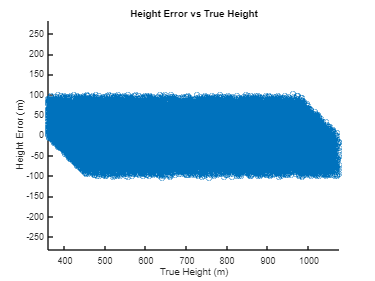


scatter(h, error_h);
axis equal;
title('Height Error NN vs True Absolute Height');
xlabel('True Absolute Height (m)');
ylabel('Height Error NN (m)');


scatter3(x, h, error_h);
%axis equal;
title('Distance from Runway vs True Absolute Height vs Height Error NN');
xlabel('Distance(m)');
ylabel('True Absolute Height (m)');
zlabel('Height Error NN (m)');


scatter3(x, y, error_h);
%axis equal;
title('Distance from Runway vs True Crosstrack Offset vs Height Error NN');
xlabel('Distance(m)');
ylabel('True Crosstrack Offset (m)');
zlabel('Height Error NN (m)');


scatter3(x, psi, error_h);
%axis equal;
title('Distance from Runway vs Yaw Angle vs Height Error NN');
xlabel('Distance(m)');
ylabel('Yaw Angle (deg)');
zlabel('Height Error NN (m)');

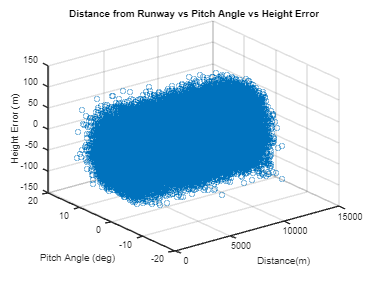


scatter3(x, theta, error_h);
%axis equal;
title('Distance from Runway vs Pitch Angle vs Height Error NN');
xlabel('Distance(m)');
ylabel('Pitch Angle (deg)');
zlabel('Height Error NN (m)');

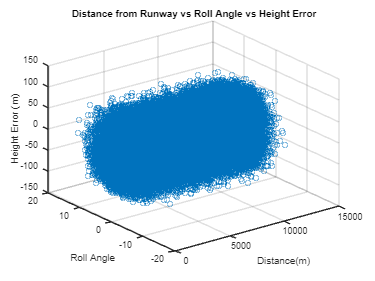



scatter3(x, phi, error_h);
%axis equal;
title('Distance from Runway vs Roll Angle vs Height Error NN');
xlabel('Distance(m)');
ylabel('Roll Angle');
zlabel('Height Error NN (m)');

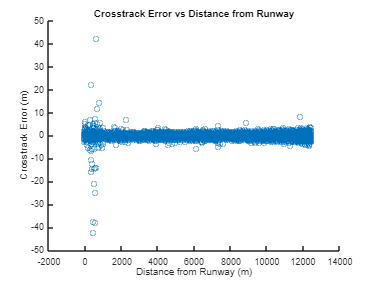


scatter(x, error_y);
axis auto; 
title('Crosstrack Error vs Distance from Runway');
xlabel('Distance from Runway (m)');
ylabel('Crosstrack Error (m)');

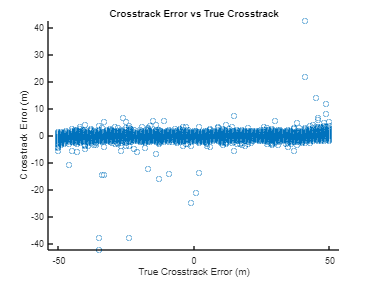


scatter(y, error_y);
axis equal;
title('Crosstrack Error NN vs True Crosstrack Offset');
xlabel('True Crosstrack Offset (m)');
ylabel('Crosstrack Error NN (m)');

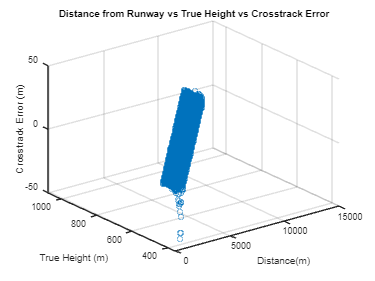


scatter3(x, h, error_y);
%axis equal;
title('Distance from Runway vs True Absolute Height vs Crosstrack Error NN');
xlabel('Distance(m)');
ylabel('True Absolute Height (m)');
zlabel('Crosstrack Error NN (m)');


%%This is the first graph I began bounding on due to its nice shape 

%Sort height values from least to greatest and error values based on corresponding height
%indices 
tab = table(h, error_y); 
tab = sortrows(tab, "h", "ascend")

tab = 74999×2 table
      h        error_y 
    ______    _________

     361.2    -0.090116
     361.2       -0.439
     361.2       2.0448
     361.2      0.57605
     361.2       2.0452
     361.2     -0.50927
     361.2      -37.552
    361.24        0.926
    361.24      -0.4278
    361.24     -0.44622
    361.24       3.8545
    361.24      -1.0127
    361.24      0.15749
    361.24     -0.79105
    361.24       5.1263
    361.24       -2.207



scatter(h, error_y);
%axis equal;
title('True Absolute Height vs Crosstrack Error NN');
xlabel('True Absolute Height (m)');
ylabel('Crosstrack Error NN (m)');


%%This is the best bet so far, find max point within a particular height
%%interval and fit a polynomial piece wise function to it- still working at
%%it a little 
max = 0; 
a = [];
b = []; 

for i = 1:length(h)
    if error_y(i) > max
        max = error_y(i); 
    end 
    if mod(i, 2000) == 0
       a(end+1) = max; 
       b(end + 1) = h(i); 
       max = 0; 
    end 
end 

%Another way to get maxes- find peaks, not as sucessful since doesn't find
%per interval- may just need to get more familar with the function though 
% [pks, locs] = findpeaks(tab.error_y, 'SortStr','descend','NPeaks',5); 
% 
% b = h(locs); 

figure 
a = a(a > 5); 
b = b(a > 5); 
b = b'; 
a = a'; 
scatter(h, error_y); 
xlim([0 1100])
ylim([0, 50])
hold on; 
f = fit(b,a,'pchip')

f =      Shape-preserving (pchip) interpolant:
       f(x) = piecewise polynomial computed from p
       with pchip extrapolation
     Coefficients:
       p = coefficient structure

plot(f); 

hold off; 


%%Now attempting to use boundary, hasn't worked so far 
% hold on; 
% boundaryline(b, a, "HatchLength",0.000000001);
% hold off; 


scatter3(x, y, error_h);
%axis equal;
title('Distance from Runway vs True Crosstrack Offset vs Crosstrack Error NN (m)');
xlabel('Distance(m)');
ylabel('True Crosstrack Offset (m)');
zlabel('Crosstrack Error NN (m)');

scatter3(x, psi, error_y);
%axis equal;
title('Distance from Runway vs Yaw Angle vs Crosstrack Error NN(m)');
xlabel('Distance(m)');
ylabel('Yaw Angle (deg)');
zlabel('Crosstrack Error NN (m)');

scatter3(x, theta, error_y);
%axis equal;
title('Distance from Runway vs Pitch Angle vs Crosstrack Error NN(m)');
xlabel('Distance(m)');
ylabel('Pitch Angle (deg)');
zlabel('Crosstrack Error NN (m)');


scatter3(x, phi, error_y);
%axis equal;
title('Distance from Runway vs Roll Angle vs Crosstrack Error NN (m)');
xlabel('Distance(m)');
ylabel('Roll Angle');
zlabel('Crosstrack Error NN (m)');